The first task is to read the image into MATLAB. 

The `fullfile` function constructs the full path to the desired file, while `imread` loads the image into MATLAB. With `double`, we are converting the data type to a floating point number for the pixel brightness values.

dataFolder = "/Users/amkhrjee/Developer/BB709/LinearAlgebra/data"; % Change this

dataFolder = "/Users/amkhrjee/Developer/BB709/LinearAlgebra/data"

I = double(imread(fullfile(dataFolder, "ct", "slice_039.png")));

ans =    256   256


Since `I` is just a matrix of image brightness values, we can get the brightness of a single pixel with simple matrix indexing.

We can even display the pixel with `imagesc`.

onePixel = I(128,128)

onePixel = 202

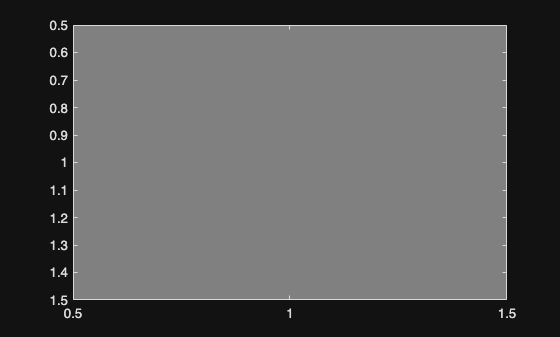

imagesc(onePixel)
colormap gray % Since the onePixel value is just a brightness level value, we can use any color!

Not only a pixel, with matrix indexing, we can even get any portion of our image!

smallPatch = I(121:128,121:128)

smallPatch =    178   173   171   174   180   181   183   184
   185   178   177   179   181   182   180   184
   191   185   184   185   186   187   185   185
   196   195   192   191   189   191   193   194
   203   200   198   198   197   195   195   196
   202   201   202   201   199   199   200   199
   203   202   202   201   201   201   201   201
   203   202   200   201   203   200   199   202


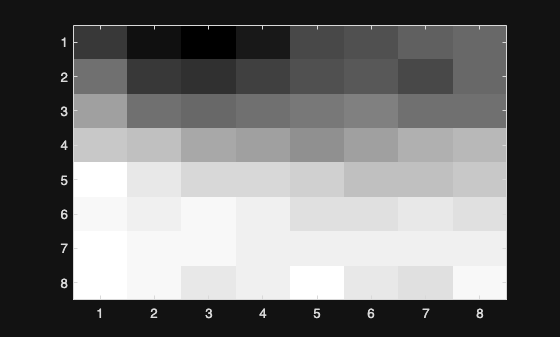

imagesc(smallPatch)
colormap gray

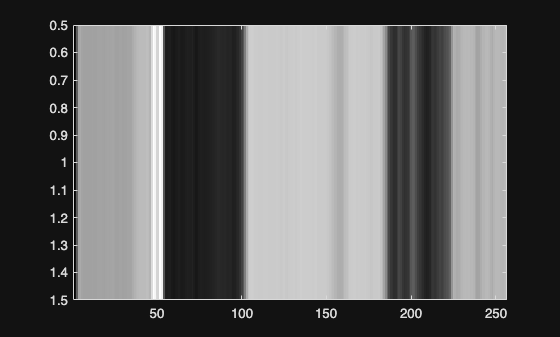

vectorSize =        65536           1


rowVector = I(128,:);
imagesc(rowVector)
colormap gray

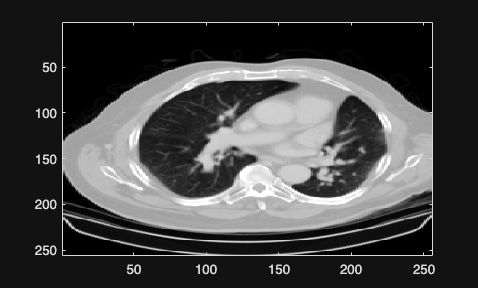

imagesc(I)
colormap gray